Definizione del **numeratore** e del **denominatore** della **FdT**.

num = 10;
den = [1 1 4];

sys = tf(num,den)


sys =
 
      10
  -----------
  s^2 + s + 4
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans =   -0.5000 + 1.9365i
  -0.5000 - 1.9365i


Tracciamento del **diagramma di Bode**.

- Il termine trinomio a denominatore prova una leggera salita del modulo prima di tendere a 0 (polo complesso coniugato).

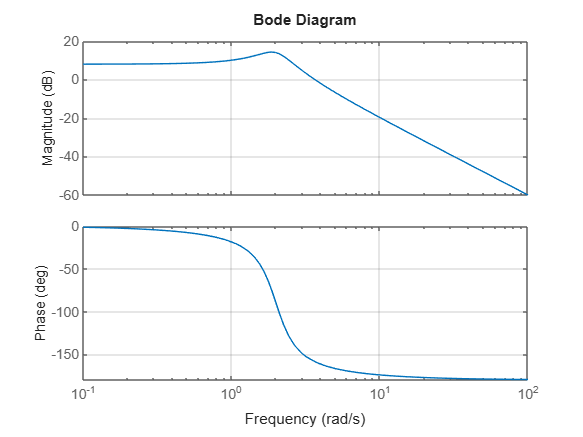

bode(sys);
grid on

Calcolo di** modulo** e** fase** per diversi valori di **w.**

[mag,phase,wout] = bode(sys);